# Copyright of this code belongs to Frank Lawless (flawless@uncc.edu).

Do not distribute this code.

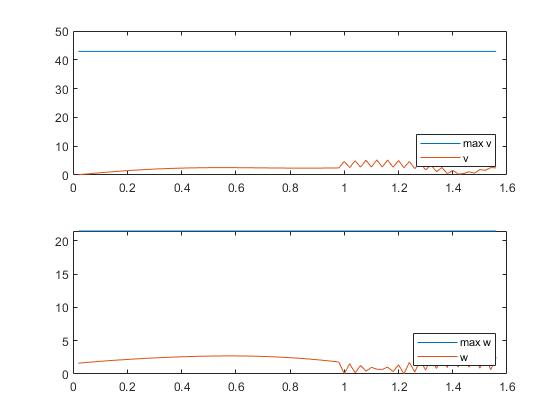

clear all ; close all
% 'D' is the distance of the pen from the base of the robot
% 'k' is the control parameter
global D h k m;

down_sample_amount = 4;

velocity_saturation = false;
v_max = 5;
w_max = 16;

v_up =v_max;
w_up= w_max;

d = 0; % delay amount \delta

% Circle
D = 2; k = 20; m = .1;h = 0.02; 
position = importdata("position_Array.mat");


l = 1;
for i = 1:down_sample_amount:length(position)
    new_position(:,l) = position(:,i);
    l = l+1;
end
position = new_position;
     
statea(:,1) =[position(1,1); position(2,1); 0];

state(:,1) =[position(1,1)-.2; position(2,1)+.2; pi/6];

xb(1) = state(1,1) + D*cos(state(3,1));
yb(1) = state(2,1) + D*sin(state(3,1));
theta(1) = state(3,1);  
theta_hat(1) = state(3,1);

xba(1) = state(1,1) + D*cos(state(3,1));
yba(1) = state(2,1) + D*sin(state(3,1));
thetaa(1) = state(3,1); 


  T = size(position,2)-1;
  t = 1:T;
  xVelocity = (position(1,t+1) - position(1,t))/h;
  yVelocity = (position(2,t+1) - position(2,t))/h;
  
  xVelocitya = (position(1,t+1) - position(1,t))/h;
  yVelocitya = (position(2,t+1) - position(2,t))/h;

for t = 1 : T
    n1(t) = 0*randn(1);
    n2(t) = 0*randn(1);

    % x= current state
    xa = [xba(t); yba(t); thetaa(t)];
    x = [xb(t); yb(t); theta_hat(t); theta(t)];
    
    % controller returns the desired velocities
    [va, wa] = controller(xa, xVelocitya(t), yVelocitya(t),position(:,t));
    [v(t), w(t)] = controller(x(1:3,1), xVelocity(t), yVelocity(t),position(:,t));
    % use the dynamics with desired velocities to generate the velocities
    dot_xa = dynamics(xa,va,wa,n1(t),n2(t));
    dot_x(:,t) = dynamics([x(1); x(2); x(4)],v(t),w(t),n1(t),n2(t));
    va = va+n1(t);
    wa = wa+n2(t);
    
    v(t) = v(t)+n1(t);
    w(t) = w(t)+n2(t);
    
    if velocity_saturation == 1
        if v(t) > v_max
            v(t) = v_max;
        elseif v(t) < -v_max
            v(t) = -v_max;
        end
    end
        
    if velocity_saturation == 1   
        if w(t) > w_max
            w(t) = w_max;
        elseif w(t) < -w_max
            w(t) = -w_max;
        end
    end
    
    
     linear_vela(t) = va;
     angular_vela(t) = wa;
     
     linear_vel(t) = v(t);
     angular_vel(t) = w(t);
     
    % centroid dynamics
    %actual
    statea(:,t+1) = statea(:,t) + h* [(va)*cos(statea(3,t)); (va)*sin(statea(3,t)); wa];  
    %noise
    state(:,t+1) = state(:,t) + h* [(v(t))*cos(state(3,t)); (v(t))*sin(state(3,t)); w(t)];
    
   

    % integrate the position to get the new position
    
    %actual
    xba(t+1) = xba(t) + dot_xa(1)*h;
    yba(t+1) = yba(t) + dot_xa(2)*h;
    thetaa(t+1) = thetaa(t) + dot_xa(3)*h;
    
    %estimated
    xb(t+1) = xb(t) + dot_x(1,t)*h;
    yb(t+1) = yb(t) + dot_x(2,t)*h;
    theta(t+1) = theta(t) + dot_x(3,t)*h;
    
    if t-d >= 1
        i=0;
    for l = t-d:t
        i = i+1;
        w_delay(i) = w(l);
    end
         theta_hat(t+1) = atan2((state(2,t+1-d)-state(2,t-d))/(v(t-d)), ...
             (state(1,t+1-d)-state(1,t-d))/(v(t-d))) + sum(w_delay)*h;
    else
        i=0;
        for l = 1:t
        i = i+1;
        w_delay(i) = w(l);

        end
        theta_hat(t+1) = theta(1)+pi+ sum(w_delay)*h;
    end

end

% reference velocity
z_dot = [0];
for i = 2:length(theta)-1
z_dot = [position(1,i+1)-position(1,i); 
            position(2,i+1)-position(2,i)]/h;
z_dot_norm(i) = norm(z_dot(:));
end


for i = 1:length(theta)
    Q(i) = k*2*cos(thetaa(i)-theta(i));
%     error_bound(i) = 2*(z_dot_norm(i))^2/Q(i);

end
 
% error norm
error = [position(1,:) - xb; position(2,:) - yb];
for i = 1:length(error)
    error_norm(i) = norm(error(:,i));
end

% velocity norm
velocity_norm(1) = 0;
for i = 2:length(xb)-1
velocity = [position(1,i)-position(1,i-1); position(2,i)-position(2,i-1)]/h;
reference_velocity_norm(i) = norm(velocity(:));
end

% velocity bounds
for i = 1:length(xb)-1
max_v(i) = max(reference_velocity_norm)+k*max(error_norm);
max_w(i) = 1/D*max(reference_velocity_norm)+k/D*max(error_norm);
end

% upper bound of e
a = (min(Q)-min(Q)*.55)^(1/2);

for t = 0:(length(xb))-1
%     e_upper1(t+1) = exp(-.5*(-a^2+min(Q))*(t*h))*error_norm(1)...
%         +max(reference_velocity_norm)/(min(k*cos(thetaa-theta)))*(1-exp(-(-a^2+max(Q))*(t*h)))^.5;
    
    e_upper2(t+1) = exp(-.5*(-a^2+min(Q))*(t*h))*error_norm(1)...
        +(max(reference_velocity_norm)^2/(a^2*(2*min(k*cos(thetaa-theta)-a^2))))^(1/2)*(1-exp(-(max(2*k*cos(thetaa-theta))-a^2)*(t*h)))^.5;
end

for t = 1:T
    v_max(t) = v_up;
    w_max(t) = w_up;
end
%bounded velocities
figure

subplot(2,1,1)
% plot([1:length(xb(1,:))-1]*h, v_max)
plot([1:length(xb(1,:))-1]*h, max_v)
hold on
plot([1:length(xb(1,:))-1]*h, abs(v))
legend('max v','v','location','southeast')
% xlim([0 0.4])
% ylim([0 0.6])
hold off

subplot(2,1,2)
% plot([1:length(xb(1,:))-1]*h, w_max)
plot([1:length(xb(1,:))-1]*h, max_w)
hold on
plot([1:length(xb(1,:))-1]*h, abs(w))
legend('max w','w','location','southeast')
% xlim([0 0.4])
% ylim([0 0.23])
hold off

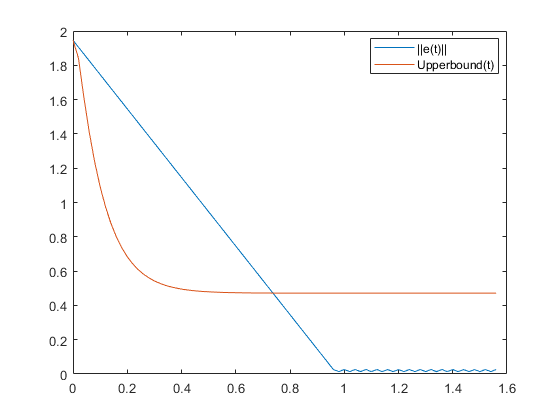


% bounded error
figure
plot([0:length(xb(1,:))-1]*h, error_norm)
hold on
plot([0:length(xb(1,:))-1]*h, e_upper2)
% plot([0:length(xb(1,:))-1]*h, e_upper1)
legend('||e(t)||','Upperbound(t)','location','best')
hold off

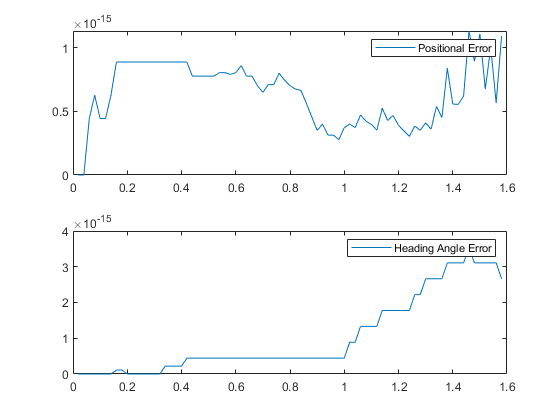




for i =1 : length(xb(1,:))
   position_distance(i) = norm([xb(1,i), yb(1,i)] - [xba(1,i), yba(1,i)] ); 
   angular_distance(i) = theta(i) - thetaa(i); 
end

subplot(2,1,1)
plot([1:length(xb(1,:))]*h, abs(position_distance));
legend("Positional Error")
subplot(2,1,2)
plot([1:length(xb(1,:))]*h, abs(angular_distance));
legend("Heading Angle Error")

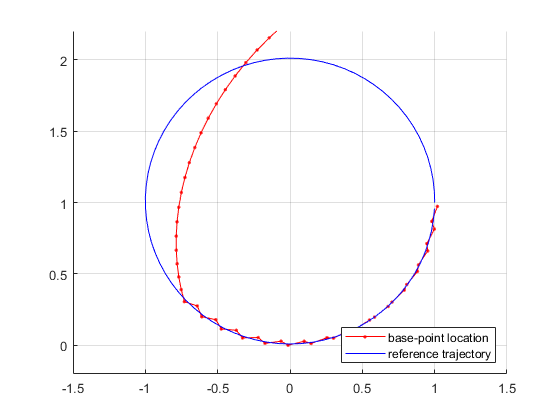

% 
% figure 
% plot([0:length(theta)-1]*h,mod(abs(thetaa-theta),2*pi))
% % hold on
% % stairs([0:d:length(max_error)-1]*h, max_error)
% % title('|\theta_{error}|')
% % hold off

% figure
% hold on
% stairs([0:d:T-d-1]*h, max_error)
% 
% title('\delta = 5, t-d<=S<=t')
% ylabel('\delta*max|n2(s)|')
% xlabel('t')
% hold off

figure
% plot(xba, yba, '.-')
hold on;
plot(xb, yb, '.-','color','r')
% plot(state(1,:), state(2,:), 'g'); 
plot(position(1,:),position(2,:),'color','b');
grid on;
legend('base-point location', 'reference trajectory', "location", 'southeast')
hold off

xlim([-1.5 1.5])
ylim([-0.2 2.2])

% 
% figure
% plot([1:size(linear_vel,2)]*h, linear_vel); hold on
% plot([1:size(angular_vel,2)]*h, angular_vel);
% legend('linear velocity (v)', 'angular velocity (w)')

function [v, w] = controller(x, xVelocity, yVelocity,position)
global D k m
 
J = [cos(x(3)) -D*sin(x(3));
    sin(x(3))  D*cos(x(3)) ];
E = x(1:2,1)- [position(1); position(2)];

% if norm(E) > m
        v_feedback = [xVelocity; yVelocity] - k*m/norm(E)*E;
%     else
%     v_feedback = [xVelocity; yVelocity] - k*E;
% end

desired_control = (J)\v_feedback;

v = desired_control(1);
w = desired_control(2);

end

function dot_x = dynamics(x,v,w,n1,n2)
global D

M = [cos(x(3)) -D*sin(x(3));
     sin(x(3))  D*cos(x(3));
     0          1          ];

dot_x = M*[v+n1; w+n2];

end
